% Step 1: Automatically detect import options
opts = detectImportOptions("iladata_1x15_500k.csv", 'TextType', 'string');

% Step 2: Set the 5th column to be imported as string (text)
opts.VariableTypes{5} = 'string';

% Step 3: Read the table using the updated import options
data = readtable("iladata_Factor_15_500k.csv", opts)

data = 512×6 table
    SampleInBuffer    SampleInWindow    TRIGGER    ILA_hist_data_20_0_    ILA_hist_sel_7_0_    LED_OBUF
    ______________    ______________    _______    ___________________    _________________    ________

           0                 0             1                0                "00000000"           1    
           1                 1             0                7                "00000001"           1    
           2                 2             0                0                "00000010"           1    
           3                 3             0                5                "00000011"           1    
           4                 4             0                0                "00000100"           1    
           5                 5             0    


prob = data.ILA_hist_data_20_0_/sum(data.ILA_hist_data_20_0_)

prob =          0
    0.0000
         0
    0.0000
         0
    0.0000
         0
    0.0000
         0
    0.0000


binaryStrs = data.ILA_hist_sel_7_0_;
x = bin2dec(extractAfter(binaryStrs, 4));  % last 4 bits
y = bin2dec(extractBefore(binaryStrs, 5)); % first 4 bits

Z = zeros(16, 16);  % 4-bit x 4-bit = 16x16 space
for i = 1:length(x)
    xi = x(i) + 1;  % MATLAB 1-based indexing
    yi = y(i) + 1;
    Z(yi, xi) = prob(i);
end
Z

Z =          0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000
    0.0000    0.0003    0.0001    0.0048    0.0000    0.0030    0.0008    0.0443    0.0000    0.0015    0.0003    0.0220    0.0002    0.0144    0.0034    0.1945
         0    0.0001         0    0.0000         0    0.0004         0    0.0001         0    0.0000         0    0.0000         0    0.0000         0    0.0000
    0.0000    0.0043    0.0000    0.0013    0.0002    0.1773    0.0000    0.0004    0.0000    0.0044    0.0000    0.0014    0.0000    0.0026    0.0000    0.0000
         0    0.0000         0    0.0002         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000
    0.0000    0.0030    0.0004    0.1870    0.0000    0.0002    0.0008    0.0043    0.0000    0.0022    0.0000    0.0052    0.0000    0.0001    0.0000    0.0008
         0    0.0007         0

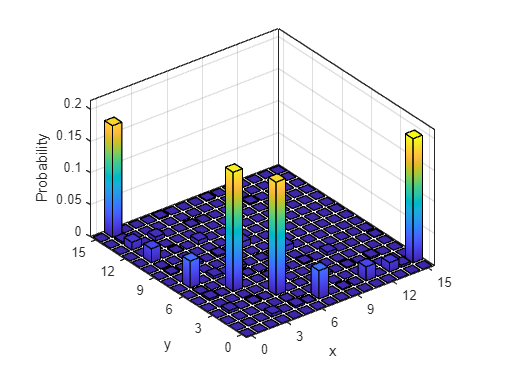

% Plot with bar3
figure;
Z_flipped = flipud(Z);
h = bar3(Z_flipped);

for k = 1:length(h)
    zdata = h(k).ZData;
    h(k).CData = zdata;
    h(k).FaceColor = 'interp';
end

colormap(parula);  % or try "jet", "hot", or "viridis" if installed
% colorbar;

xlabel('x');
ylabel('y');
zlabel('Probability');
% title('4×4-bit Integer Factorization Probability Distribution');
% view(-45, 30);  % Good angle for visibility

% Flip y-axis so y=0 is in front
% set(gca, 'YDir', 'reverse');

% Set axis limits and ticks
xlim([0.5, 16.5]);
ylim([0.5, 16.5]);
zlim([0, max(Z(:)) * 1.1]);
box on
xticks(1:3:16); xticklabels(0:3:15);
yticks(1:3:16); yticklabels(15:-3:0);
print(gcf, '4x4bIntFac_plot_Factor_15', '-dpng', '-r300');  % 300 DPI PNG